# This script focuses on the pid tuning of the Rhino 300 rpm motor(RMCS-5033)

% Initialising the variable for the continuous transfer function of the
% motor

R = 1.6;      % Armature Resistance(Ohm)
L = 0.001;    % Inductance(Henry)
K = 0.00636;  % Motor constant( V/rad)
b = 2.7e-6;   % Viscous friction of the motor at no load)
J_wheel = 0.1562;  % kgm^2 
J_rotor = 1e-6;   % negligible rotor inertia
N = 52.1;          % gear ratio(as present in the documentation of the motor)

J_reflected = J_wheel/(N^2);

J_total = J_rotor + J_reflected; % total inertia on the motor(using macannum wheel)



## Creating the transfer function s

s = tf('s');

% Standard DC motor transfer function derived using physics and electronics
G = K / ((J_total*s + b)*(L*s + R) + K^2);

## Display the open loop transfer function

disp('Open loop transfer function of the motor');

Open loop transfer function of the motor


G


G =
 
                  0.00636
  ---------------------------------------
  5.854e-08 s^2 + 9.367e-05 s + 4.477e-05
 
Continuous-time transfer function.


## Analyse the physical response for 12 V input

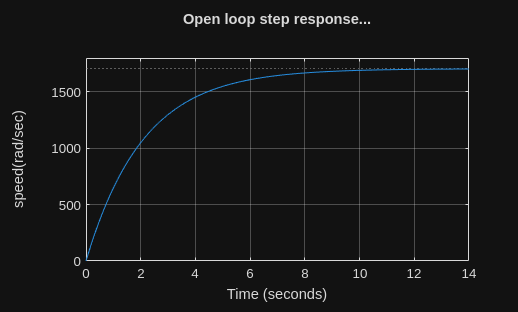

figure;
step(12 * G);
title('Open loop step response...');
ylabel('speed(rad/sec)');
grid on;